# Introduction

This live script contains examples of reachable workspaces for 3D robots. For each example this includes: 

- DH Parameters

- Generated Workspace

% Symbolic vars

syms theta1 theta2 theta3 theta4 theta5 theta6 real
syms d1 d2 d3 d4 real

# Example 1 - AdeptThree Robot Arm

This is an example workspace search for the 4 DOF [AdeptThree Robot Arm](https://www.intechopen.com/chapters/15855).

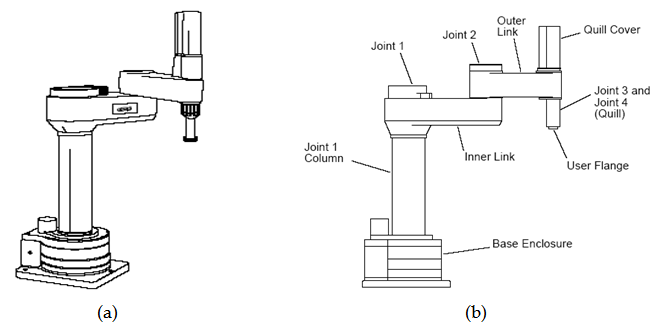

% DH parameters
test_dh = [18.5 0 42 theta1; ...
           16 pi 0 theta2; ...
           0 0 d3 0; ...
           0 0 7 theta4]

$$test\_dh = \left(\begin{array}{cccc} \frac{37}{2} & 0 & 42 & \theta_{1}\\ 16 & \pi & 0 & \theta_{2}\\ 0 & 0 & d_{3} & 0\\ 0 & 0 & 7 & \theta_{4} \end{array}\right)$$

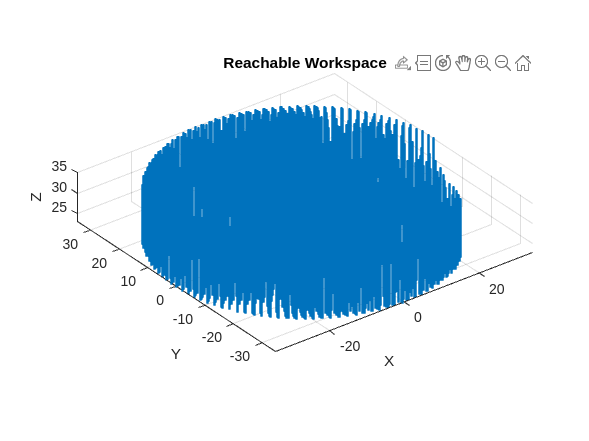

% Parameter ranges
theta1_range = arr2Rad(linspace(0,300, 50));
theta2_range = arr2Rad(linspace(0,300, 50));
d3_range = linspace(0,12, 50);
% Note the specification states 540°, but anything past 360° is redundant
theta4_range = arr2Rad(linspace(0,360, 50));
test_map = containers.Map({'theta1', 'theta2', 'd3','theta4'}, ...
    {theta1_range, theta2_range, d3_range, theta4_range}); 
% Workspace plotting function
plot3dworkspace(test_dh, test_map, @get_alternative_dh_transform)

# Example 2 - PUMA 560

This is an example using 6 DOF [PUMA 560](https://hive.blog/hive-196387/@juecoree/forward-kinematics-of-puma-560-robot-using-dh-method).

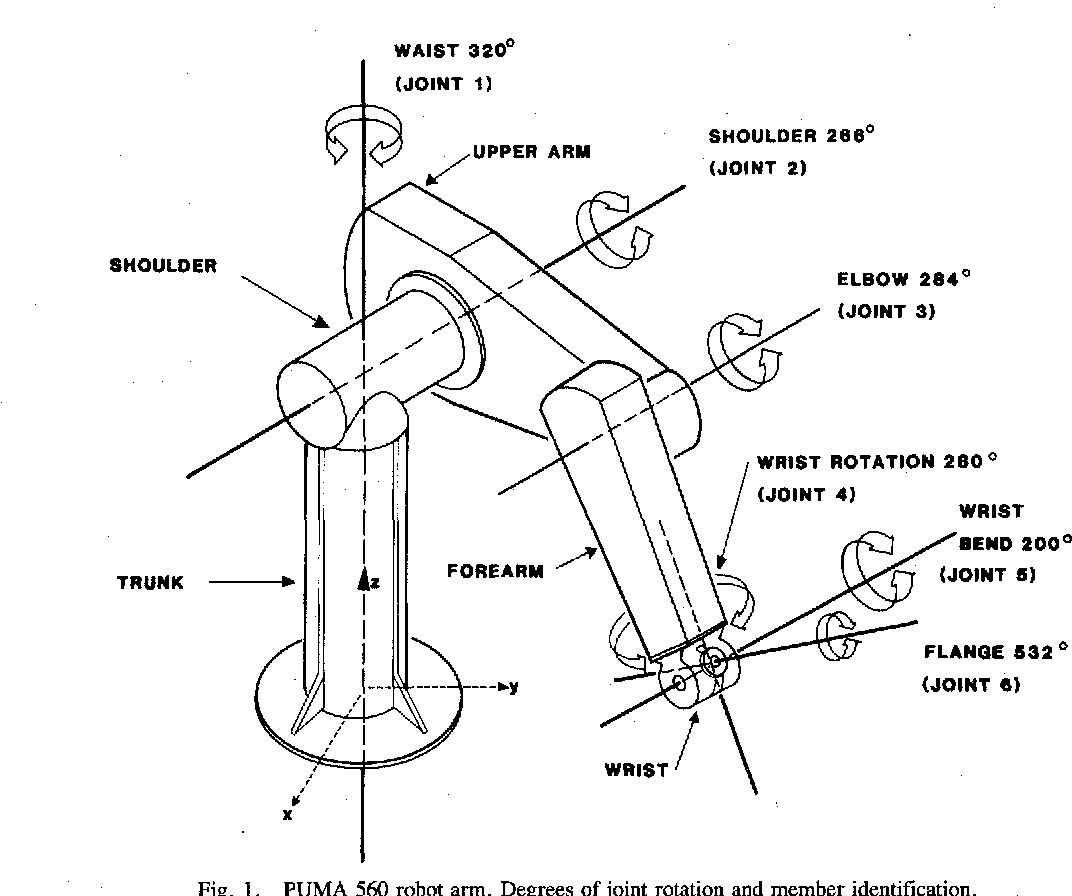

% DH parameters
test_dh = [0 -pi/4 671 theta1; ...
           431 0 139 theta2; ...
           -20 pi/4 0 theta3; ...
           0 -pi/4 431 theta4; ...
           0 pi/4 0 theta5; ...
           0 0 56 theta6;]

$$test\_dh = \left(\begin{array}{cccc} 0 & -\frac{\pi }{4} & 671 & \theta_{1}\\ 431 & 0 & 139 & \theta_{2}\\ -20 & \frac{\pi }{4} & 0 & \theta_{3}\\ 0 & -\frac{\pi }{4} & 431 & \theta_{4}\\ 0 & \frac{\pi }{4} & 0 & \theta_{5}\\ 0 & 0 & 56 & \theta_{6} \end{array}\right)$$


% Parameter ranges
theta1_range = arr2Rad(linspace(-160,160,50));
theta2_range = arr2Rad(linspace(-225,45,50));
theta3_range = arr2Rad(linspace(-45,225,50));
theta4_range = arr2Rad(linspace(-110,170,5));
theta5_range = arr2Rad(linspace(-100,100,5));
theta6_range = arr2Rad(linspace(-180,180,5));

test_map = containers.Map({'theta1', 'theta2', 'theta3','theta4', 'theta5', 'theta6'}, ...
     {theta1_range, theta2_range, theta3_range, theta4_range, theta5_range, theta6_range}) 

test_map =   Map with properties:

        Count: 6
      KeyType: char
    ValueType: any


final transformation matrix from base to end-effector:


expressions for position:
x = 431*cos(theta1)*cos(theta2) - (431*sin(theta1))/2 - 20*cos(theta3)*(cos(theta1)*cos(theta2) - (2^(1/2)*sin(theta1)*sin(theta2))/2) + 20*sin(theta3)*(cos(theta1)*sin(theta2) + (2^(1/2)*cos(theta2)*sin(theta1))/2) - (139*2^(1/2)*sin(theta1))/2 - 28*2^(1/2)*((2^(1/2)*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - (2^(1/2)*sin(theta1)*sin(theta2))/2) - sin(theta3)*(cos(theta1)*sin(theta2) + (2^(1/2)*cos(theta2)*sin(theta1))/2)))/2 - (2^(1/2)*((2^(1/2)*sin(theta3)*(cos(theta1)*cos(theta2) - (2^(1/2)*sin(theta1)*sin(theta2))/2))/2 - sin(theta1)/2 + (2^(1/2)*sin(theta3)*(cos(theta1)*sin(theta2) + (2^(1/2)*cos(theta2)*sin(theta1))/2))/2))/2 + (2^(1/2)*sin(theta4)*(sin(theta1)/2 + (2^(1/2)*cos(theta3)*(cos(theta1)*sin(theta2) + (2^(1/2)*cos(theta2)*sin(theta1))/2))/2 + (2^(1/2)*sin(theta3)*(cos(theta1)*cos(theta2) - (2^(1/2)*sin(theta1)*sin(theta2))/2))/2))/2) + 28*2^(1/2)*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - (2^(1/2)*sin(theta1)*si

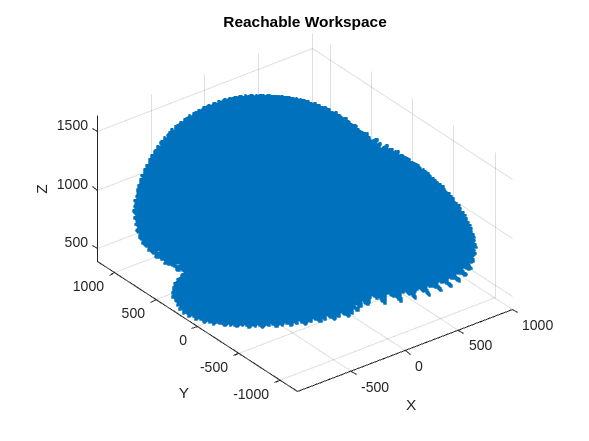

% Workspace plotting function + timing
plot3dworkspace(test_dh, test_map, @get_alternative_dh_transform, true)

% A somewhat convoluted PDF export procedure to save a PDF of the .mlx file
% for github. You can ignore this.
file_name = 'plot3dworkspace_examples';
current_mlx = which(file_name);
[path_to_file, name, ext] = fileparts(current_mlx);
mlx_path = fullfile(path_to_file, (file_name + ".mlx"));
pdf_path = fullfile(path_to_file, (file_name + ".pdf"));
export(mlx_path, pdf_path);

function out = arr2Rad(A)
    out = arrayfun(@(angle) deg2rad(angle), A);
end

function T = get_alternative_dh_transform(a,alpha,d,theta)
T = [cos(theta) -cos(alpha)*sin(theta) sin(alpha)*sin(theta) a*cos(theta)
     sin(theta) cos(alpha)*cos(theta) -sin(alpha)*sin(theta) a*sin(theta)
     0 sin(alpha) cos(alpha) d
     0 0 0 1];
end